# SSP Biomechanics Analysis Pipeline

Comparative evaluation of surgical methods in the treatment of chronic irreparable supraspinatus tears: a biomechanical study

Authors: E. Koumantou, C. J. Feroussis, E. D. Pasiou, S. K. Kourkoulis

This script processes load-displacement data from biomechanical tests and calculates key metrics: Max Load, Stiffness, and Energy.

## Configuration

clear; clc; close all;

% --- PATHS ---
DATA_FOLDER = "C:\Users\elena\OneDrive - Imperial College London\2_NTUA\2_SSP_Project\Data\Selected_data";
RESULTS_FOLDER = "C:\Users\elena\OneDrive - Imperial College London\2_NTUA\2_SSP_Project\Data\Results";

% Create Results folder if it doesn't exist
if ~exist(RESULTS_FOLDER, 'dir')
    mkdir(RESULTS_FOLDER);
end

% --- SUBGROUP ASSIGNMENTS ---
% These define which OPERATED samples belong to each treatment group.
% Non-operated samples are automatically assigned to 'NON' (control) group.
TFL_IDS = {'B1', 'B10', 'B11', 'C1', 'C2', 'D1', 'D2', 'D3', 'D4', 'D5', 'D6', 'D7', 'D8'};
MSC_IDS = {'B5', 'B6', 'B7', 'B9', 'D9', 'D10', 'D11', 'D12', 'D13', 'D14', 'D15'};

% --- ANALYSIS PARAMETERS ---
R2_THRESHOLD = 0.99;        % Minimum R² for linear region
WINDOW_FRACTION = 0.1;      % Fraction of data points for sliding window
MIN_WINDOW = 5;             % Minimum window size

fprintf('SSP Biomechanics Analysis Pipeline\n');

SSP Biomechanics Analysis Pipeline


fprintf('==================================\n\n');

fprintf('Data folder: %s\n', DATA_FOLDER);

Data folder: C:\Users\elena\OneDrive - Imperial College London\2_NTUA\2_SSP_Project\Data\Selected_data


fprintf('Results folder: %s\n\n', RESULTS_FOLDER);

Results folder: C:\Users\elena\OneDrive - Imperial College London\2_NTUA\2_SSP_Project\Data\Results



## Helper Functions

# classifySample(filename, tflIDs, mscIDs)

Parse filename to determine sample classification

Inputs:

-       filename - Name of the CSV file (e.g., 'SSP_2025-03-17_D1_NO.csv')

-       tflIDs   - Cell array of TFL group subject IDs

-       mscIDs   - Cell array of MSC group subject IDs

Outputs: 

-       sampleID  - Subject identifier (e.g., 'D1')

-       condition - 'NO' or 'OPER'

-       subgroup  - 'NON', 'TFL', or 'MSC'

Remove .csv extension and split by underscore

function [sampleID, condition, subgroup] = classifySample(filename, tflIDs, mscIDs)
    % CLASSIFYSAMPLE Parse filename to determine sample classification
    %
    % Inputs:
    %   filename - Name of the CSV file (e.g., 'SSP_2025-03-17_D1_NO.csv')
    %   tflIDs   - Cell array of TFL group subject IDs
    %   mscIDs   - Cell array of MSC group subject IDs
    %
    % Outputs:
    %   sampleID  - Subject identifier (e.g., 'D1')
    %   condition - 'NO' or 'OPER'
    %   subgroup  - 'NON', 'TFL', or 'MSC'
    
    % Remove .csv extension and split by underscore
    nameParts = strsplit(erase(filename, '.csv'), '_');
    
    % Determine condition
    if any(strcmp(nameParts, 'NO'))
        condition = 'NO';
    elseif any(strcmp(nameParts, 'OPER'))
        condition = 'OPER';
    else
        condition = 'Unknown';
    end
    
    % Find sample ID and determine subgroup
    sampleID = 'Unknown';
    subgroup = 'Unassigned';
    
    % Non-operated samples are always in NON group
    if strcmp(condition, 'NO')
        subgroup = 'NON';
    end
    
    % Check each part against known IDs
    for i = 1:length(nameParts)
        part = nameParts{i};
        if any(strcmp(tflIDs, part))
            sampleID = part;
            if strcmp(condition, 'OPER')
                subgroup = 'TFL';
            end
            break;
        elseif any(strcmp(mscIDs, part))
            sampleID = part;
            if strcmp(condition, 'OPER')
                subgroup = 'MSC';
            end
            break;
        elseif ~isempty(regexp(part, '^[BCD]\d{1,2}$', 'once'))
            % Fallback: match pattern like B1, C2, D15
            sampleID = part;
        end
    end
end


# findBestStiffness (x, y, windowSize, r2Threshold)

Find the stiffest linear region using sliding window

Inputs:

-       x  - Displacement values (mm)

-       y  - Load values (N)

-       windowSize  - Number of points in sliding window

-       r2Threshold - Minimum R² to consider region as linear

Outputs: 

-       slope     - Stiffness (N/mm)

-       intercept - Y-intercept of linear fit

-       r2        - R² of the best fit

-       startIdx  - Start index of linear region

-       endIdx    - End index of linear region

function [slope, intercept, r2, startIdx, endIdx] = findBestStiffness(x, y, windowSize, r2Threshold)
    % FINDBESTSTIFFNESS Find the stiffest linear region using sliding window
    %
    % Inputs:
    %   x           - Displacement values (mm)
    %   y           - Load values (N)
    %   windowSize  - Number of points in sliding window
    %   r2Threshold - Minimum R² to consider region as linear
    %
    % Outputs:
    %   slope     - Stiffness (N/mm)
    %   intercept - Y-intercept of linear fit
    %   r2        - R² of the best fit
    %   startIdx  - Start index of linear region
    %   endIdx    - End index of linear region
    
    nPoints = length(x);
    
    % Initialize outputs
    slope = NaN;
    intercept = NaN;
    r2 = NaN;
    startIdx = 0;
    endIdx = 0;
    
    if nPoints < windowSize
        warning('Insufficient data points (%d) for window size (%d)', nPoints, windowSize);
        return;
    end
    
    bestSlope = 0;
    bestR2 = -Inf;
    
    % Sliding window loop
    for i = 1:(nPoints - windowSize + 1)
        idx = i:(i + windowSize - 1);
        xWin = x(idx);
        yWin = y(idx);
        
        % Linear regression
        p = polyfit(xWin, yWin, 1);
        yPred = polyval(p, xWin);
        
        % Calculate R²
        ssRes = sum((yWin - yPred).^2);
        ssTot = sum((yWin - mean(yWin)).^2);
        if ssTot == 0
            r2Win = 0;
        else
            r2Win = 1 - (ssRes / ssTot);
        end
        
        currentSlope = p(1);
        
        % Criteria: highest slope with R² above threshold
        if r2Win >= r2Threshold
            if currentSlope > bestSlope
                bestSlope = currentSlope;
                slope = currentSlope;
                intercept = p(2);
                r2 = r2Win;
                startIdx = i;
                endIdx = i + windowSize - 1;
            end
        end
        
        % Fallback: track best R² if no region meets threshold
        if r2Win > bestR2 && bestSlope == 0
            bestR2 = r2Win;
            slope = currentSlope;
            intercept = p(2);
            r2 = r2Win;
            startIdx = i;

Found 46 CSV files to process.



            endIdx = i + windowSize - 1;
        end
    end
end

## Process All Files

% Get list of CSV files
files = dir(fullfile(DATA_FOLDER, '*.csv'));
nFiles = length(files);

fprintf('Found %d CSV files to process.\n\n', nFiles);
% Initialize results table
results = table();

for f = 1:nFiles
    filename = files(f).name;
    filepath = fullfile(DATA_FOLDER, filename);
    
    try
        % Classify sample
        [sampleID, condition, subgroup] = classifySample(filename, TFL_IDS, MSC_IDS);
        
        if strcmp(condition, 'Unknown')
            fprintf('[!] Skipping %s: Could not determine NO/OPER.\n', filename);
            continue;
        end
        
        % Read data
        data = readtable(filepath);
        
        % Handle different column names
        if ismember('LoadN', data.Properties.VariableNames)
            load_N = data.LoadN;
        elseif ismember('LoadkN', data.Properties.VariableNames)
            load_N = data.LoadkN * 1000;
        else
            fprintf('[!] Skipping %s: No load column found.\n', filename);
            continue;
        end
        
        displacement_mm = data.Crossheadmm;
        
        % Truncate at max load (failure point)
        [maxLoad, maxIdx] = max(load_N);
        x = displacement_mm(1:maxIdx);
        y = load_N(1:maxIdx);
        
        % Calculate energy (area under curve)
        energy_mJ = trapz(x, y);
        
        % Calculate stiffness
        windowSize = max(MIN_WINDOW, round(length(x) * WINDOW_FRACTION));
        [stiffness, ~, r2Score, startIdx, endIdx] = findBestStiffness(x, y, windowSize, R2_THRESHOLD);
        
        % Add to results
        newRow = table(...
            {filename}, {sampleID}, {subgroup}, maxLoad, stiffness, energy_mJ, r2Score, startIdx, endIdx, ...

[OK] SSP_2022-12-06_B10_NO.csv -> NON: MaxLoad=483.1N, Stiffness=242.4N/mm
[OK] SSP_2022-12-08_B10_OPER.csv -> TFL: MaxLoad=72.4N, Stiffness=42.3N/mm
[OK] SSP_2022-12-08_B11_NO.csv -> NON: MaxLoad=395.1N, Stiffness=213.8N/mm
[OK] SSP_2022-12-08_B11_OPER.csv -> TFL: MaxLoad=99.1N, Stiffness=20.2N/mm
[OK] SSP_2022-12-08_B1_OPER.csv -> TFL: MaxLoad=143.1N, Stiffness=32.5N/mm
[OK] SSP_2022-12-08_B5_NO.csv -> NON: MaxLoad=341.9N, Stiffness=147.3N/mm
[OK] SSP_2022-12-08_B5_OPER.csv -> MSC: MaxLoad=172.0N, Stiffness=44.3N/mm
[OK] SSP_2022-12-17_B6_NO.csv -> NON: MaxLoad=594.0N, Stiffness=298.6N/mm
[OK] SSP_2022-12-17_B7_NO.csv -> NON: MaxLoad=653.0N, Stiffness=304.2N/mm
[OK] SSP_2022-12-17_B7_OPER.csv -> MSC: MaxLoad=120.0N, Stiffness=28.4N/mm
[OK] SSP_2022-12-17_B9_NO.csv -> NON: MaxLoad=499.0N, Stiffness=348.3N/mm
[OK] SSP_2022-12-17_B9_OPER.csv -> MSC: MaxLoad=135.0N, Stiffness=26.6N/mm
[OK] SSP_2024-10-26_C1_NO.csv -> NON: MaxLoad=458.4N, Stiffness=137.3N/mm
[OK] SSP_2024-10-26_C2_NO.csv 

            'VariableNames', {'Filename', 'SampleID', 'Subgroup', 'MaxLoad_N', 'Stiffness_N_mm', ...
                             'Energy_mJ', 'R2_Score', 'Linear_Start_Idx', 'Linear_End_Idx'});


Processed 46 samples successfully.


        results = [results; newRow];
        
        fprintf('[OK] %s -> %s: MaxLoad=%.1fN, Stiffness=%.1fN/mm\n', ...

                filename, subgroup, maxLoad, stiffness);

=== Sample Results ===


                    Filename                    SampleID    Subgroup    MaxLoad_N    Stiffness_N_mm    Energy_mJ    R2_Score    Linear_Start_Idx    Linear_End_Idx
    ________________________________________    ________    ________    _________    ______________    _________    ________    ________________    ______________

    {'SSP_2022-12-06_B10_NO.csv'           }    {'B10'}     {'NON'}      483.05          242.45         642.79      0.99659           196                234      
    {'SSP_2022-12-08_B10_OPER.csv'         }    {'B10'}     {'TFL'}       72.37          42.276         100.46      0.99916           261                302      
    {'SSP_2022-12-08_B11_NO.csv'         

    catch ME
        fprintf('[X] Error processing %s: %s\n', filename, ME.message);
    end
end

fprintf('\nProcessed %d samples successfully.\n', height(results));


=== Group Statistics ===



## Display Results

disp(' ');
disp('=== Sample Results ===');
disp(results);

## Generate Group Statistics

groups = unique(results.Subgroup);
nGroups = length(groups);

fprintf('\n=== Group Statistics ===\n\n');

statsTable = table();

for g = 1:nGroups
    groupName = groups{g};
    groupData = results(strcmp(results.Subgroup, groupName), :);
    n = height(groupData);
    
    statsRow = table(...
        {groupName}, n, ...

    Subgroup    Count    MaxLoad_Mean    MaxLoad_Std    Stiffness_Mean    Stiffness_Std    Energy_Mean    Energy_Std
    ________    _____    ____________    ___________    ______________    _____________    ___________    __________

    {'MSC'}      10         154.59         19.164           43.639           11.326          670.55          351.8  
    {'NON'}      23         418.17         145.11           175.61            88.31          843.63         382.59  
    {'TFL'}      13         108.47         46.851           29.843           16.468          523.41         620.15  



        mean(groupData.MaxLoad_N), std(groupData.MaxLoad_N), ...
        mean(groupData.Stiffness_N_mm), std(groupData.Stiffness_N_mm), ...
        mean(groupData.Energy_mJ), std(groupData.Energy_mJ), ...
        'VariableNames', {'Subgroup', 'Count', ...
                         'MaxLoad_Mean', 'MaxLoad_Std', ...


Saved: C:\Users\elena\OneDrive - Imperial College London\2_NTUA\2_SSP_Project\Data\Results\Experiment_Master_Log_Detailed.csv


                         'Stiffness_Mean', 'Stiffness_Std', ...
                         'Energy_Mean', 'Energy_Std'});
    statsTable = [statsTable; statsRow];
end

Saved: C:\Users\elena\OneDrive - Imperial College London\2_NTUA\2_SSP_Project\Data\Results\Group_Statistics_Detailed.csv



disp(statsTable);

## Save Results to CSV

resultsPath = fullfile(RESULTS_FOLDER, 'Experiment_Master_Log_Detailed.csv');
writetable(results, resultsPath);
fprintf('\nSaved: %s\n', resultsPath);

statsPath = fullfile(RESULTS_FOLDER, 'Group_Statistics_Detailed.csv');
writetable(statsTable, statsPath);
fprintf('Saved: %s\n', statsPath);

## Visualization: Group Comparison Bar Charts

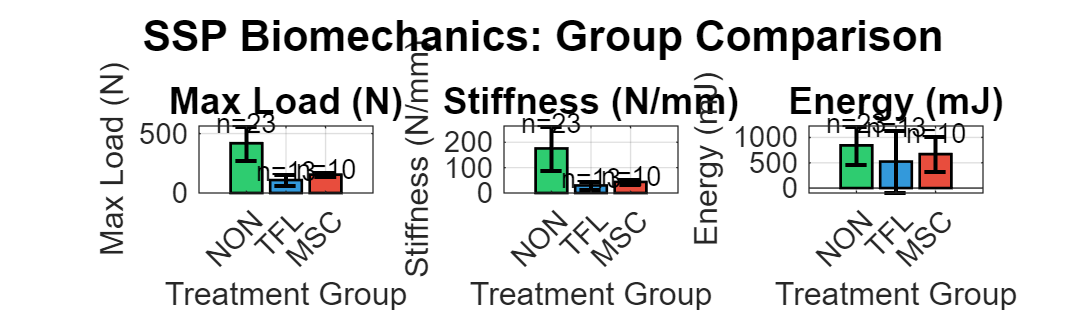

figure('Position', [100, 100, 1400, 400]);

groupOrder = {'NON', 'TFL', 'MSC'};
colors = [0.18, 0.80, 0.44;   % Green for NON
          0.20, 0.60, 0.86;   % Blue for TFL
          0.91, 0.30, 0.24];  % Red for MSC

metrics = {'MaxLoad_N', 'Stiffness_N_mm', 'Energy_mJ'};
titles = {'Max Load (N)', 'Stiffness (N/mm)', 'Energy (mJ)'};

for m = 1:3
    subplot(1, 3, m);
    
    means = zeros(1, 3);
    stds = zeros(1, 3);
    counts = zeros(1, 3);
    
    for g = 1:3
        groupData = results(strcmp(results.Subgroup, groupOrder{g}), :);
        counts(g) = height(groupData);
        if counts(g) > 0
            means(g) = mean(groupData.(metrics{m}));
            stds(g) = std(groupData.(metrics{m}));
        end
    end
    
    b = bar(means, 'FaceColor', 'flat', 'EdgeColor', 'k', 'LineWidth', 1);
    b.CData = colors;
    
    hold on;
    errorbar(1:3, means, stds, 'k', 'LineStyle', 'none', 'LineWidth', 1.5, 'CapSize', 8);
    
    % Add sample counts
    for g = 1:3
        text(g, means(g) + stds(g) + max(means)*0.05, sprintf('n=%d', counts(g)), ...
             'HorizontalAlignment', 'center', 'FontSize', 10);
    end
    
    set(gca, 'XTickLabel', groupOrder, 'FontSize', 11);
    xlabel('Treatment Group', 'FontSize', 12);

    ylabel(titles{m}, 'FontSize', 12);

Saved: C:\Users\elena\OneDrive - Imperial College London\2_NTUA\2_SSP_Project\Data\Results\Combined_Group_Plots.png


    title(titles{m}, 'FontSize', 14, 'FontWeight', 'bold');
    grid on;
    box on;
end

sgtitle('SSP Biomechanics: Group Comparison', 'FontSize', 16, 'FontWeight', 'bold');

% Save figure
plotPath = fullfile(RESULTS_FOLDER, 'Combined_Group_Plots.png');
saveas(gcf, plotPath);
fprintf('Saved: %s\n', plotPath);

## Visualization: Load-Displacement Curves by Group

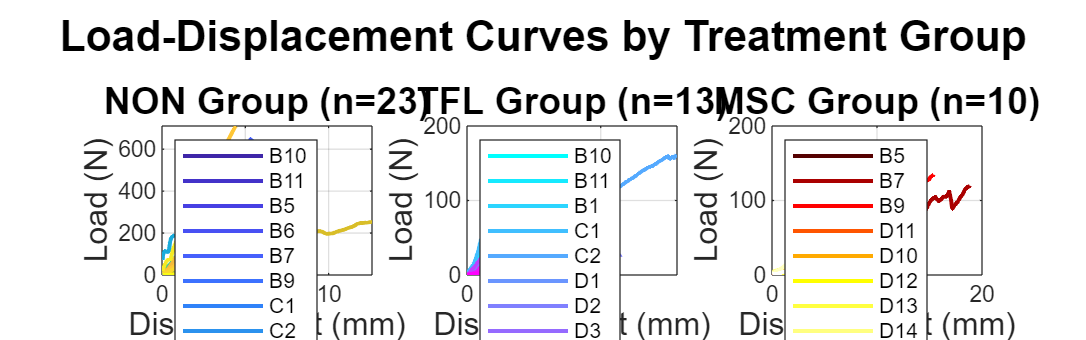

figure('Position', [100, 100, 1600, 500]);

for g = 1:3
    subplot(1, 3, g);
    groupName = groupOrder{g};
    groupData = results(strcmp(results.Subgroup, groupName), :);
    nSamples = height(groupData);
    
    % Color map
    if strcmp(groupName, 'NON')
        cmap = parula(max(nSamples, 1));
    elseif strcmp(groupName, 'TFL')
        cmap = cool(max(nSamples, 1));
    else
        cmap = hot(max(nSamples, 1));
    end
    
    legendEntries = {};
    
    for s = 1:nSamples
        filename = groupData.Filename{s};
        filepath = fullfile(DATA_FOLDER, filename);
        
        data = readtable(filepath);
        
        if ismember('LoadN', data.Properties.VariableNames)
            load_N = data.LoadN;
        else
            load_N = data.LoadkN * 1000;
        end
        
        displacement_mm = data.Crossheadmm;
        
        % Truncate at max load
        [~, maxIdx] = max(load_N);
        x = displacement_mm(1:maxIdx);
        y = load_N(1:maxIdx);
        
        plot(x, y, 'Color', cmap(s, :), 'LineWidth', 1.5);
        hold on;
        
        legendEntries{end+1} = groupData.SampleID{s};

    end
    
    xlabel('Displacement (mm)', 'FontSize', 12);
    ylabel('Load (N)', 'FontSize', 12);
    title(sprintf('%s Group (n=%d)', groupName, nSamples), 'FontSize', 14, 'FontWeight', 'bold');
    legend(legendEntries, 'Location', 'northwest', 'FontSize', 8);
    grid on;
    box on;
end

sgtitle('Load-Displacement Curves by Treatment Group', 'FontSize', 16, 'FontWeight', 'bold');

% Save individual group plots
for g = 1:3
    figure('Position', [100, 100, 800, 600]);
    groupName = groupOrder{g};
    groupData = results(strcmp(results.Subgroup, groupName), :);
    nSamples = height(groupData);
    
    if strcmp(groupName, 'NON')
        cmap = parula(max(nSamples, 1));
    elseif strcmp(groupName, 'TFL')
        cmap = cool(max(nSamples, 1));
    else
        cmap = hot(max(nSamples, 1));
    end
    
    legendEntries = {};
    
    for s = 1:nSamples
        filename = groupData.Filename{s};
        filepath = fullfile(DATA_FOLDER, filename);
        
        data = readtable(filepath);
        
        if ismember('LoadN', data.Properties.VariableNames)
            load_N = data.LoadN;
        else
            load_N = data.LoadkN * 1000;
        end
        
        displacement_mm = data.Crossheadmm;
        
        [~, maxIdx] = max(load_N);
        x = displacement_mm(1:maxIdx);
        y = load_N(1:maxIdx);
        
        plot(x, y, 'Color', cmap(s, :), 'LineWidth', 1.5);
        hold on;
        
        legendEntries{end+1} = groupData.SampleID{s};
    end
    
    xlabel('Displacement (mm)', 'FontSize', 12);

Saved: C:\Users\elena\OneDrive - Imperial College London\2_NTUA\2_SSP_Project\Data\Results\Plot_NON.png
Saved: C:\Users\elena\OneDrive - Imperial College London\2_NTUA\2_SSP_Project\Data\Results\Plot_TFL.png
Saved: C:\Users\elena\OneDrive - Imperial College London\2_NTUA\2_SSP_Project\Data\Results\Plot_MSC.png


    ylabel('Load (N)', 'FontSize', 12);
    title(sprintf('%s Group (n=%d)', groupName, nSamples), 'FontSize', 14, 'FontWeight', 'bold');
    legend(legendEntries, 'Location', 'northwest', 'FontSize', 9);
    grid on;
    box on;
    
    plotPath = fullfile(RESULTS_FOLDER, sprintf('Plot_%s.png', groupName));
    saveas(gcf, plotPath);
    fprintf('Saved: %s\n', plotPath);
    close(gcf);
end

## Visualization: Stiffness Region Example

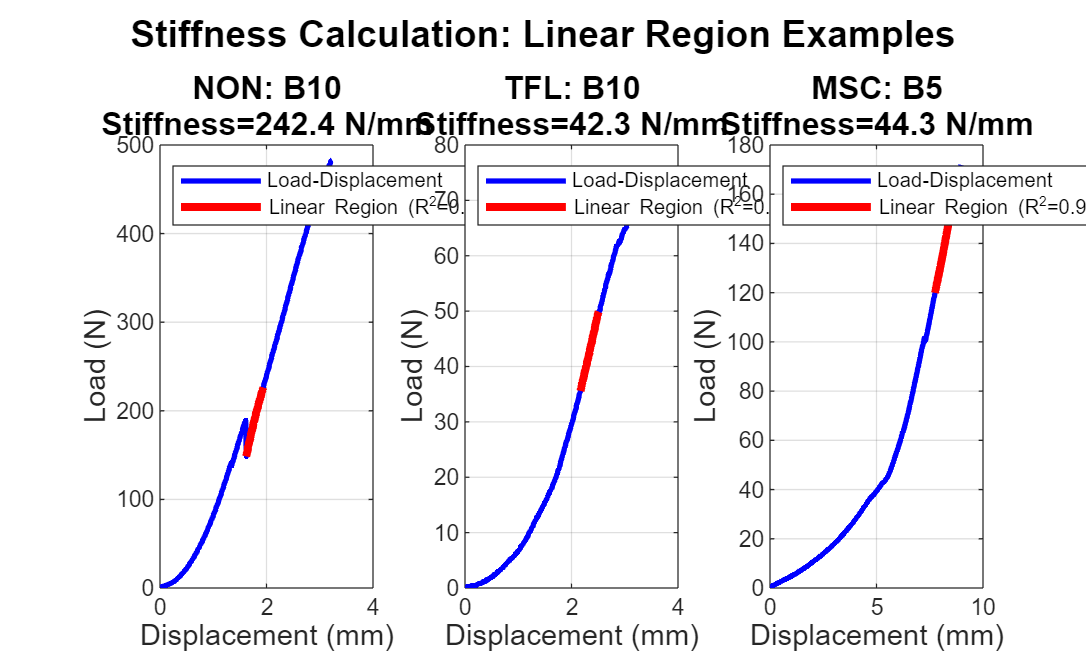

figure('Position', [100, 100, 1000, 600]);

% Pick one sample from each group to show
for g = 1:3
    subplot(1, 3, g);
    groupName = groupOrder{g};
    groupData = results(strcmp(results.Subgroup, groupName), :);
    
    if height(groupData) == 0
        continue;
    end
    
    % Get first sample
    sampleRow = groupData(1, :);
    filename = sampleRow.Filename{1};
    filepath = fullfile(DATA_FOLDER, filename);
    
    data = readtable(filepath);
    
    if ismember('LoadN', data.Properties.VariableNames)
        load_N = data.LoadN;
    else
        load_N = data.LoadkN * 1000;
    end
    
    displacement_mm = data.Crossheadmm;
    
    [~, maxIdx] = max(load_N);
    x = displacement_mm(1:maxIdx);
    y = load_N(1:maxIdx);
    
    startIdx = sampleRow.Linear_Start_Idx;
    endIdx = sampleRow.Linear_End_Idx;
    
    % Plot full curve
    plot(x, y, 'b-', 'LineWidth', 2, 'DisplayName', 'Load-Displacement');
    hold on;
    
    % Highlight linear region
    if startIdx > 0 && endIdx > 0 && endIdx <= length(x)
        plot(x(startIdx:endIdx), y(startIdx:endIdx), 'r-', 'LineWidth', 3, ...
             'DisplayName', sprintf('Linear Region (R^2=%.4f)', sampleRow.R2_Score));
    end
    
    xlabel('Displacement (mm)', 'FontSize', 11);
    ylabel('Load (N)', 'FontSize', 11);

    title(sprintf('%s: %s\nStiffness=%.1f N/mm', groupName, sampleRow.SampleID{1}, ...

Saved: C:\Users\elena\OneDrive - Imperial College London\2_NTUA\2_SSP_Project\Data\Results\Stiffness_Region_Examples.png


                  sampleRow.Stiffness_N_mm), 'FontSize', 12);
    legend('Location', 'northwest');
    grid on;
    box on;

end

ANALYSIS COMPLETE


sgtitle('Stiffness Calculation: Linear Region Examples', 'FontSize', 14, 'FontWeight', 'bold');


Total samples processed: 46


Results saved to: C:\Users\elena\OneDrive - Imperial College London\2_NTUA\2_SSP_Project\Data\Results


plotPath = fullfile(RESULTS_FOLDER, 'Stiffness_Region_Examples.png');


Files generated:


saveas(gcf, plotPath);

  - Experiment_Master_Log_Detailed.csv


fprintf('Saved: %s\n', plotPath);

  - Group_Statistics_Detailed.csv


  - Combined_Group_Plots.png


  - Plot_NON.png, Plot_TFL.png, Plot_MSC.png


## Summary

fprintf('\n');

  - Stiffness_Region_Examples.png


fprintf('============================================\n');
fprintf('ANALYSIS COMPLETE\n');
fprintf('============================================\n');
fprintf('\nTotal samples processed: %d\n', height(results));
fprintf('Results saved to: %s\n', RESULTS_FOLDER);
fprintf('\nFiles generated:\n');
fprintf('  - Experiment_Master_Log_Detailed.csv\n');
fprintf('  - Group_Statistics_Detailed.csv\n');
fprintf('  - Combined_Group_Plots.png\n');
fprintf('  - Plot_NON.png, Plot_TFL.png, Plot_MSC.png\n');
fprintf('  - Stiffness_Region_Examples.png\n');